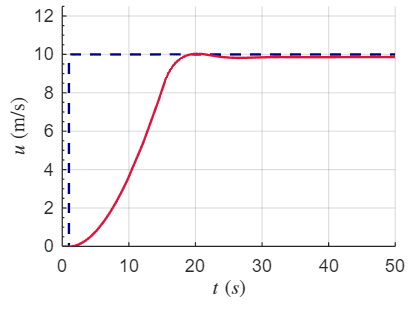

clear
clc


% 0 Controller value

Kp_1 = 97;

Kp_2 = -51.2;

Ki_2 = -0.055;

Kp_3 = -0.057;

Ki_3 = -0.0003;

% 1 Run model
open('Pitch_Trim.slx')
out = sim('Pitch_Trim.slx');

% 2 Extract time and signal data
t = out.u.Time;
u = out.u.Data;
step = out.step.Data;

% 3 Compute step response characteristics

% Plot for verification
[ha, pos] = tight_subplot(1,1, ...   % Nh, Nw
                          [0.08 0.08], ...
                          [0.21 0.02], ...    % marg_h [bottom top]
                          [0.15 0.05]);       % marg_w [left  right]

ax = ha(1);            % handle to the only axes
axes(ax);              % activate it

plot(t, step, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1.5);
hold on
plot(t, u, 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5);
hold off

set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';

xlim([0 50]);
ylim([0 12.5]);

xlabel('$t \; (s)$', 'Interpreter', 'latex');
ylabel('$u \; (\mathrm{m/s})$', 'Interpreter', 'latex');


grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

% Set figure size
set(gcf, 'Position', [0 0 400 300]);


% Compute step response characteristics
info = stepinfo(u, t);
disp('Step Response Characteristics:');

Step Response Characteristics:


disp(info);

         RiseTime: 10.3000
    TransientTime: 17.8232
     SettlingTime: 17.8236
      SettlingMin: 9.0242
      SettlingMax: 10.0322
        Overshoot: 0.4031
       Undershoot: 0.0445
             Peak: 10.0322
         PeakTime: 20.4426

